# System Integration and Test Simulation

Configure a simulation that uses the following:

- Truth Locations - Field-collected ADSB data recorded with an RTL-SDR

- Detections and Sensor-based Tracks:

- Active radar (fusionRadarSensor)

- ADSB data (gpsSensor and ADSBReceiver)

- TrackFuser for C2 level tracks

- OSPA Metric, trackAssignmentMetrics, and errorMetrics for track accuracy analysis

close all force; clear; addpath('../HelperFunctions/')

## Configure Simulation

### Setup Scenario

Import truth location of aircraft and convert to trajectories for simulation

mapOrigin = [42.39423231362 -70.95934958874 0]; % Also defined in helperNed2ecefTrack, helperEcef2nedTrack, and fusionAlgorithm.m
load('TruthData2.mat') % Latest truth trajectories 3/3/26

Scenario Creation includes configuring the Active Radar Sensor

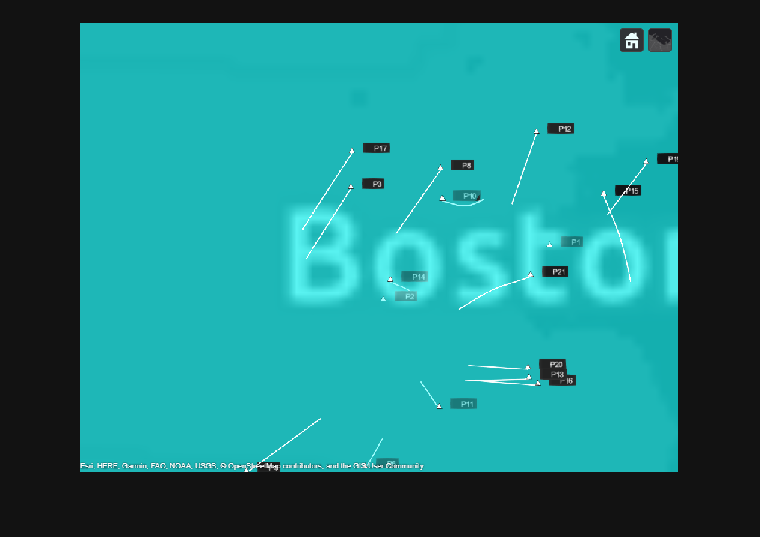

truncatedStopTime = 60; % Limit Simulation time (s)
scenario = helperCreateScenario(tuningData, mapOrigin,truncatedStopTime);
mapViewer = trackingGlobeViewer('ReferenceLocation',mapOrigin,'Basemap','streets-dark');
campos(mapViewer, mapOrigin + [0 -0.4 1e5]);
drawnow;
plotScenario(mapViewer,scenario);
snapshot(mapViewer);

### Secondary Sensor Configuration

Add ADSB for secondary target detection

Define Accuracy parameters for the gps sensor and assign ADSB transponder a

horAccuracy = 30;   % meters (NACp = 9)
vertAccuracy = 45;  % meters (NACp = 9)
velAccuracy = 0.6;  % m/s (NACv = 3)

gps = gpsSensor('PositionInputFormat','Geodetic',...
    'HorizontalPositionAccuracy',horAccuracy,...
    'VerticalPositionAccuracy',vertAccuracy,'VelocityAccuracy',velAccuracy);
numTargets = numel(scenario.Platforms)-2; % Two platforms in scene are the sensor towers

Leverage a helper function to store GPS transponder in a structure.

transponderStruct = helperCreateTX(numTargets, gps);

### Configure ADSB Receiver for SSR

adsbRx = adsbReceiver('ReceiverIndex',2);

### Configure Tracker

[tracker,activeRadarSpec,targetSpec] = helperCreateTracker(scenario);

### Configure Track Fuser

You fuse radar tracks with ADS-B tracks obtained from the ADS-B receiver. To do this, you configure a central `trackFuser` object.

% Define the radar source configuration
radarConfig = fuserSourceConfiguration('SourceIndex',1,...
    'IsInitializingCentralTracks',false,...
    'CentralToLocalTransformFcn',@helperEcef2nedTrack,...
    'LocalToCentralTransformFcn',@helperNed2ecefTrack);

## **Step 1 - Adjust Coordinate Transform Configuration to Match Data**

**Directions:**

By running the script as configured, you should see that the adsbTracks are placed far from the truth positions of the targets. By adjusting the "CentralToLocalTransformFcn" and "LocalToCentralTransformFcn" to use the correct coordinate transforms, this should fix the issue.

Note - While I have given you the coordinate transforms, they are only flipped for the adsbConfig. In practice, you may have to generate this transforms yourself. It is powerful to use the visualization tools to check that you have done this setup correctly while configuring the functions.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% type "doc fuserSourceConfiguration" in the Command Window to find the documentation page for this function
% ADJUST THE adsbConfig's "CentralToLocalTransformFcn" and "LocalToCentralTransformFcn" to perform the
% transforms in the correct direction, ie opposite of the radarConfig:

% Define the adsb source configuration
adsbConfig = fuserSourceConfiguration('SourceIndex',2,...
    'IsInitializingCentralTracks',true,...
    'CentralToLocalTransformFcn',@helperNed2ecefTrack,...
    'LocalToCentralTransformFcn',@helperEcef2nedTrack); % This is solution - revert for the example

### Instantiate the track fuser 

User-defined trackFuser

Define Process Noise for Fuser

procNoiseHorz = targetSpec{1}.MaxHorizontalAcceleration^2/3;
procNoiseVert = targetSpec{1}.MaxVerticalAcceleration^2/3;
fuseProcNoise = blkdiag(procNoiseHorz,procNoiseHorz,procNoiseVert);

Instantiate Fuser

fuser = trackFuser('FuserIndex',3,'MaxNumSources',2,...
    "AssignmentThreshold",[100 250],...
    "StateFusion",'Intersection',...
    'StateFusionParameters','trace',...
    'ProcessNoise',fuseProcNoise, ...
    'ConfirmationThreshold',[2 3],... 
    'DeletionThreshold',[2 2],... 
    'SourceConfigurations',{radarConfig;adsbConfig});

## Phase 1 — Short Visual-Check Loop - Check User Config

Load Pre-recorded Sensor Data

load('SensorData2.mat'); % RENAME CLEANUP

Reset Scenario, Tracker, Viewer, and Transponders

clear(mapViewer);
restart(scenario);
release(tracker);

Split dataset for easier parsing within simulation

trackerUpdateInterval = 1; % seconds
[activeRadarData] = helperSplitSensorData(sensorData, scenario.StopTime, trackerUpdateInterval);

### Run Short Simulation

Run a small number of steps with the User-defined fuser so you can see whether ADS-B tracks are landing on or far from the truth positions. If the adsbConfig is wrong, tracks will appear displaced on the globe.

**Check the figure and consider:**

- If ADS-B/fused tracks are displaced from truth, fix adsbConfig above and re-run

- If tracks overlay the truth, your config is correct — proceed to Phase 2

phase1Steps = 15;  % Sufficient to see ADS-B and fused tracks appear
fprintf('\n--- Phase 1: Running %d steps with User-defined fuser for visual check ---\n', phase1Steps);


--- Phase 1: Running 15 steps with User-defined fuser for visual check ---


a1 = tic;

% Reset for Phase 1
clear(mapViewer);
restart(scenario);
release(tracker);
reset(adsbRx);

for i = 1:numTargets
    reset(transponderStruct(i).adsbTx);
end
plotPlatform(mapViewer,[scenario.Platforms{3:end}],TrajectoryMode="Full");

% Labels and colors
adsblabel = "       ADS-B";
radarlabel = "  Radar";
fusedlabel = string(sprintf('%s\n',"","Fused"));
adsbclr = [183 70 255]/255;
radarclr = [255 255 17]/255;
fusedclr = [255 105 41]/255;

wgs84 = wgs84Ellipsoid('meter');

for ind = 1:phase1Steps
    advance(scenario);

    % Plot Radar Coverage
    covcon = coverageConfig(scenario);
    plotCoverage(mapViewer,covcon,"ECEF")

    % Truth positions
    for i = 1:numel(scenario.Platforms)
        poseStruct = pose(scenario.Platforms{i},'CoordinateSystem','Geodetic');
        poseStruct.PlatformID = scenario.Platforms{i}.PlatformID;
        truePoseGPS(i) = poseStruct;
    end
    truePosePlot = platformPoses(scenario);
    plotPlatform(mapViewer, truePosePlot, 'ECEF');

    % Plot Radar Detections
    helperPlotActiveRadarData(mapViewer, activeRadarSpec, activeRadarData(ind));

    % Define Current Simulation Time
    time = scenario.SimulationTime;

    % ADS-B processing
    adsbTracks     = objectTrack.empty;
    adsbTracksPlot = objectTrack.empty;
    radarTracks    = objectTrack.empty;
    fusedTracks    = objectTrack.empty;

    % Generate ADSB Messages
    for i = 3:numel(truePoseGPS)
        position = truePoseGPS(i).Position;
        velocity = truePoseGPS(i).Velocity;
        if ~isnan(position)
            adsbMessages(i-2,1) = transponderStruct(i-2).adsbTx(position,velocity);
        end
    end

    % Generate ADSB Tracks
    adsbTracks = adsbRx(adsbMessages, time);
    adsbTracks = adsbTracks';
    clear adsbMessages
    adsbTracks = helperEnsureTimeAndParams(adsbTracks, time, helperEcefParams());

    % Convert to NED for globe viewer
    for i = 1:length(adsbTracks)
        adsbTracksPlot(i) = helperEcef2nedTrack(adsbTracks(i));
    end

    % Generate Radar Tracks
    radarTracksStruct = trackingAlgorithm_mex({activeRadarData(ind)},targetSpec,activeRadarSpec);
    radarTracks = helperConvertToObjectTrack(radarTracksStruct);
    radarTracks = helperEnsureTimeAndParams(radarTracks, time, helperNedParams());

    % Fusion — Fuser using user's adsbConfig
    if isLocked(fuser) || ~isempty([adsbTracks;radarTracks])
        fusedTracks = fuser([adsbTracks;radarTracks], time);
    end

    % Plot all tracks
    mapViewer = helperPlotTracks(3,mapViewer,adsbTracksPlot,radarTracks,fusedTracks,...
        adsblabel,adsbclr,radarlabel,radarclr,fusedlabel,fusedclr);

    drawnow;
end

fprintf('Phase 1 complete (%.1f s).  Check the globe viewer.\n', toc(a1));

Phase 1 complete (26.6 s).  Check the globe viewer.


**Check the figure and consider:**

- If ADS-B/fused tracks are displaced from truth, fix adsbConfig above and re-run

- If tracks overlay the truth, your config is correct — proceed to Phase 2

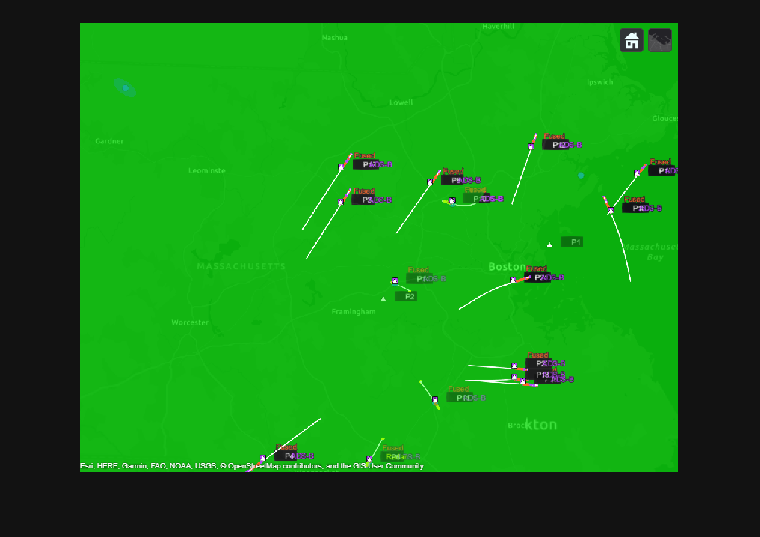

snapshot(mapViewer);

## Phase 2 — Full Simulation with MEX Fuser - Show in Full Simulation

Phase 2 uses the MEX-compiled fusionAlgorithm (which has its own correct hardcoded config) for the full-duration simulation with metrics.

This is wrapped in helperRunFullSimulation() for a clean, single function call:

### Run Full Simulation

helperRunFullSimulation re-creates the scenario, tracker, and fuser from scratch using the MEX-compiled fusionAlgorithm_mex, runs the full simulation, and returns all logged data and metrics.

% Clean up the interpreted fuser from Phase 1
clear fuser trackingAlgorithm_mex

--- Phase 2: Running full simulation with MEX fuser ---


results = helperRunFullSimulation(tuningData, mapOrigin);

  Running 60 steps ...
  Sim loop done (25.8 s wall-clock).


Phase 2 complete (25.8 s wall-clock).



### Take Snapshot of Viewer (from Phase 2 - Full Simulation)

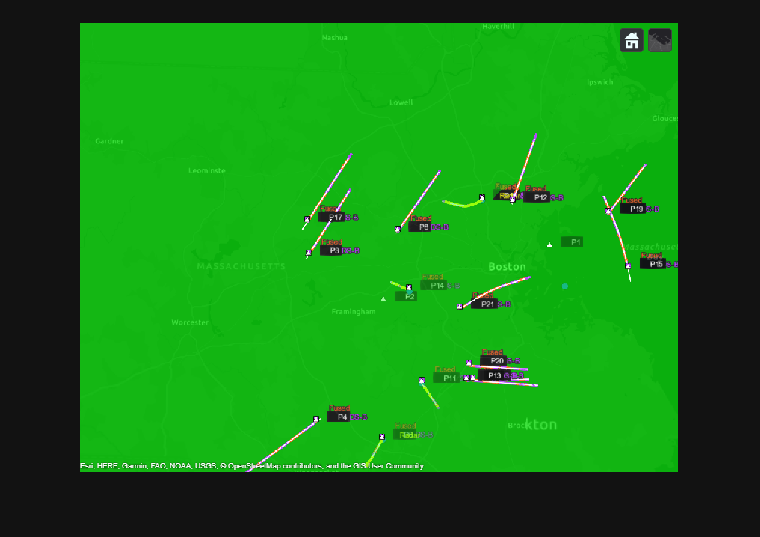

snapshot(results.mapViewer);

## Collect and Visualize Metrics

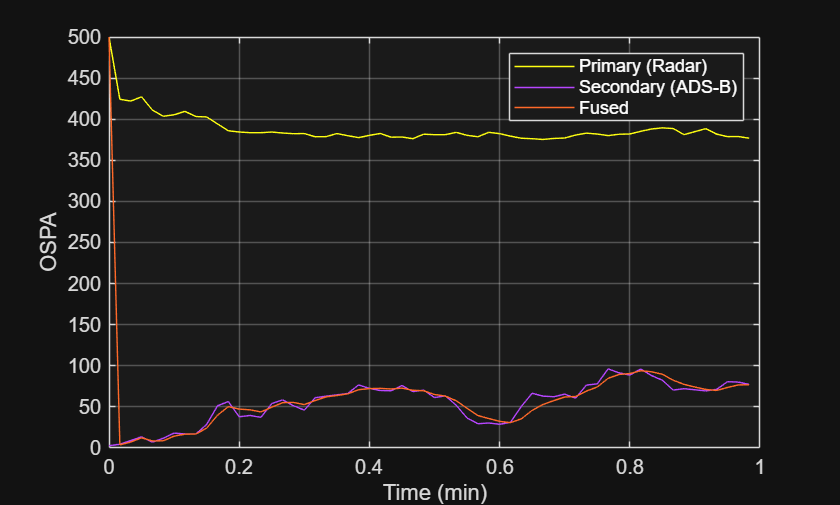

ospa = trackOSPAMetric('CutoffDistance',500,'Distance','posabserr');

helperCollectOSPAMetricsAndPlot(ospa,results);

### Plot RMS Values

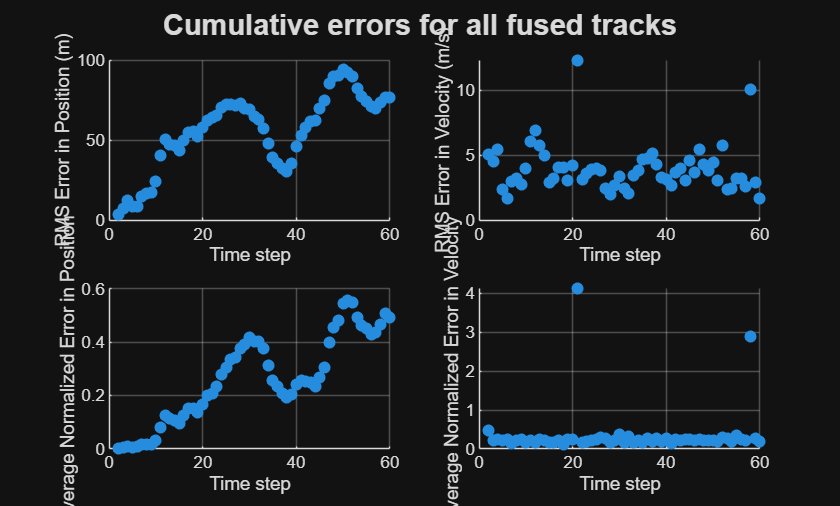

helperPlotRMS(results)

## BONUS:

Consider running "Exercise3_BONUS" for further breakdown of metrics